recObj=audiorecorder(16000,8,2);
disp('Record your voice-Start speaking.')

Record your voice-Start speaking.


recordblocking(recObj, 5);
disp('End of Recording.')

End of Recording.



play(recObj)

ans =   audioplayer with properties:

       SampleRate: 16000
    BitsPerSample: 8
      NumChannels: 2
         DeviceID: -1
    CurrentSample: 513
     TotalSamples: 80000
          Running: 'on'
         StartFcn: []
          StopFcn: []
         TimerFcn: []
      TimerPeriod: 0.0500
              Tag: ''
         UserData: []
             Type: 'audioplayer'


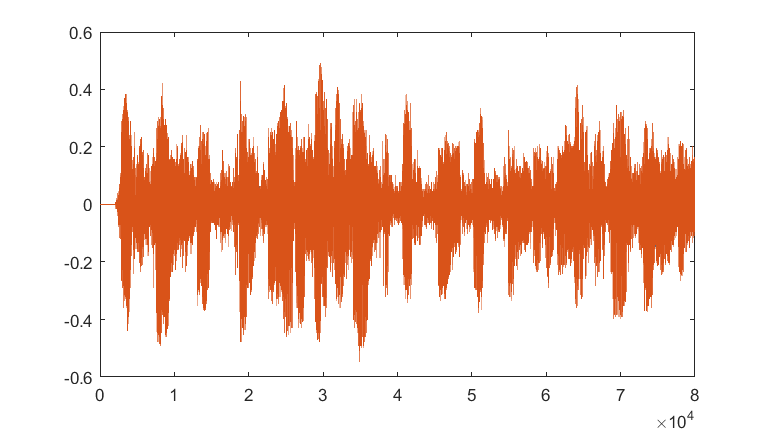

y = getaudiodata(recObj);
figure('Units','normalized','Position',[0.4 0.4 0.4 0.4])
plot(y)

audiowrite('User.wav', y, 16000);

[audioIn,sr1] = audioread('User.wav');
%sr1=inf.SampleRate;
aFE = audioFeatureExtractor("SampleRate",sr1, "Window",hamming(round(0.03*sr1),"periodic"), "OverlapLength",round(0.02*sr1), "mfcc",true, "mfccDelta",true, "pitch",true, "spectralCentroid",true);
Test_Features = extract(aFE,audioIn(:,1));
numVec2 = size(Test_Features,1);
Mean3 = mean(Test_Features,1,"omitnan");
Std3 = std(Test_Features,[],1,"omitnan");
Test_Features = (Test_Features-Mean3)./Std3;
Test_prediction = predict(classifier,Test_Features);
Test_prediction = categorical(string(Test_prediction));
predname=mode(Test_prediction);
misclassrate=sum(predname~=Test_prediction)/numel(Test_prediction);
if misclassrate>=0.85
    disp('Not Identified')
    disp('You are not authorized')
else
    disp(predname)
    disp('You are authorized')
end

Naman


You are authorized
